clear;
close all;
clc;

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

SNR = -10:1:20;      % Relação sinal-ruído variando de -10 a 20 dB
N_SNR = length(SNR); % Comprimento do vetor SNR

B = 8;               % Número de bits por símbolo
M_QAM = 2^B;         % Tamanho da constelação QAM (256 pontos)

M = 100;             % Número de subportadoras no sistema OFDM
L = 10;              % Comprimento do canal em amostras
K = L;               % Comprimento do prefixo em amostras
N = M+K;             % Comprimento do bloco de dados

N_BLK = 1;           % Número de blocos de dados transmitidos

N_EQ  = 2;           % Número de equalizadores

N_FFT  = 1024;       % Número de pontos para a FFT

freq_N = 2*pi*linspace(-0.5,0.5,N_FFT); % Frequências normalizadas para a FFT
freq_M = 2*pi*linspace(-0.5,0.5,M);     % Frequências das subportadoras

BER = zeros(N_SNR,N_EQ,2);                 % Matriz da taxa de erro de bits

A_cp = [zeros(K,M-K) eye(K); eye(M)];      % Matriz CP
R_cp = [zeros(M,K) eye(M)];                % Matriz de remoção CP
   
A_zp = [eye(M); zeros(K,M)];               % Matriz ZP
R_zp = [eye(M) [eye(K); zeros(M-K,K)]];    % Matriz de remoção ZP

x  = zeros(N*N_BLK,2);                     % Dados transmitidos
Px = zeros(2,1);                           % Potência dos dados transmitidos

y_p       = zeros(N,N_BLK,2,N_SNR);        % Sinais recebidos no canal para cada bloco e SNR 
m_mod_hat = zeros(M,N_BLK,N_EQ,2,N_SNR);   % Símbolos demodulados
m_bit_hat = zeros(B*M*N_BLK,N_EQ,2,N_SNR); % Bits estimados

**Modelagem do sistema de transmissão**

m_bit = randi([0 1],B*M*N_BLK,1);              % Gerando bits aleatórios
m_mod = qammod(m_bit,M_QAM,'InputType','bit'); % Modulação QAM
m_mod = reshape(m_mod,M,N_BLK);                % Reorganização vetor de símbolos modulados

**CP-OFDM**

s = sqrt(M)*A_cp*ifft(m_mod);              % OFDM symbols with cyclic prefix
x(:,1) = reshape(s,[],1);                  % Parallel to serial conversion
Px(1)  = norm(x(:,1))^2/length(x(:,1));    % Average transmission power

**ZP-OFDM**

s = sqrt(M)*A_zp*ifft(m_mod);              % OFDM symbols with zero-padding

x(:,2) = reshape(s,[],1);                  % Parallel to serial conversion
Px(2)  = norm(x(:,2))^2/length(x(:,2));    % Average transmission power

**Modelagem do canal H**

h = randn(L+1,1) +1i*rand(L+1,1);          % Generating FIR channel with i.i.d. Rayleigh distribution and L order
h = h/norm(h);                             % Channel normalization

h_freq = fft(h,N_FFT);                     % Frequency response H(w)
lambda = fft(h,M);                         % Frequency response H(2pim/M)

z = fftfilt(h,x);                          % Filter signal by channel

**Gráfico 1**

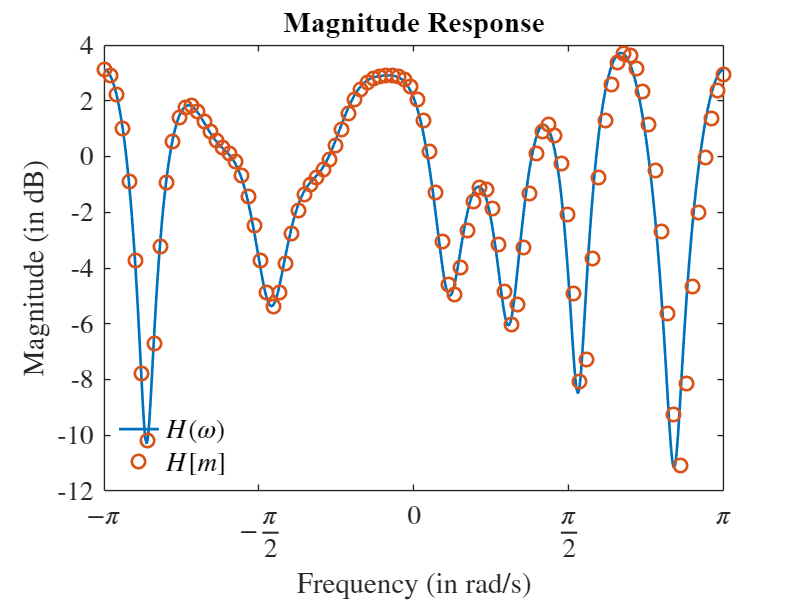

figure;

set(gcf,'position',[0 0 800 600])

plot(freq_N,fftshift(20*log10(abs(h_freq))),'linewidth',linewidth,'markersize',markersize);
hold on;
plot(freq_M,fftshift(20*log10(abs(lambda))),'o','linewidth',linewidth,'markersize',markersize);

title('Magnitude Response','fontname',fontname,'fontsize',fontsize);
xlabel('Frequency (in rad/s)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude (in dB)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

legend({'$H(\omega)$','$H[m]$'},'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
legend box off

xticks([-pi -pi/2 0 pi/2 pi]);

xlim([-pi,pi]);

set(gca,'ticklabelinterpreter','latex', ...
    'xticklabel',{'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'}, ...
    'fontname',fontname,'fontsize',fontsize);

**Modelagem do sistema de recepção**

for snr_ind = 1:N_SNR 
    v  = randn(N*N_BLK,1) + 1i*randn(N*N_BLK,1);           % AWGN noise
    Pv = norm(v)^2/length(v);                              % Average noise power
    
    v_1 = sqrt(((Px(1)/Pv))*(10^(-SNR(snr_ind)/10)))*v;    % True AWGN noise
    v_2 = sqrt(((Px(2)/Pv))*(10^(-SNR(snr_ind)/10)))*v;    % True AWGN noise

    y = z + [v_1 v_2];                                     % Received signal
    
    y_p(:,:,1,snr_ind) = reshape(y(:,1),N,N_BLK);          % Serial to parallel conversion of the CP-OFDM symbols
    y_p(:,:,2,snr_ind) = reshape(y(:,2),N,N_BLK);          % Serial to parallel conversion of the ZP-OFDM symbols

    Equalizer_zf = diag(1./lambda);                                                % ZF equalizer matrix
    Equalizer_mmse = diag(conj(lambda)./(abs(lambda).^2 + 10^(-SNR(snr_ind)/10))); % MMSE equalizer matrix

    m_mod_hat(:,:,1,3,snr_ind) = Equalizer_zf*fft(R_cp*y_p(:,:,3,snr_ind))/sqrt(M);   % ZF equalization
    m_mod_hat(:,:,2,3,snr_ind) = Equalizer_mmse*fft(R_cp*y_p(:,:,3,snr_ind))/sqrt(M); % MMSE equalization
    
    % Q-QAM demodulation

    m_bit_hat(:,1,3,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,3,snr_ind),[],1),Q,'OutputType','bit'); % ZF
    m_bit_hat(:,2,3,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,3,snr_ind),[],1),Q,'OutputType','bit'); % MMSE
    
    % Bit-error rate computation

    [~,BER(snr_ind,1,3)] = biterr(m_bit_hat(:,1,3,snr_ind),m_bit); % ZF
    [~,BER(snr_ind,2,3)] = biterr(m_bit_hat(:,2,3,snr_ind),m_bit); % MMSE

    m_mod_hat(:,:,1,4,snr_ind) = Equalizer_zf*fft(R_zp*y_p(:,:,4,snr_ind))/sqrt(M);   % ZF equalization
    m_mod_hat(:,:,2,4,snr_ind) = Equalizer_mmse*fft(R_zp*y_p(:,:,4,snr_ind))/sqrt(M); % MMSE equalization
    
    % Q-QAM demodulation

    m_bit_hat(:,1,4,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,4,snr_ind),[],1),Q,'OutputType','bit'); % ZF
    m_bit_hat(:,2,4,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,4,snr_ind),[],1),Q,'OutputType','bit'); % MMSE
    
    % Bit-error rate computation

    [~,BER(snr_ind,1,4)] = biterr(m_bit_hat(:,1,4,snr_ind),m_bit); % ZF
    [~,BER(snr_ind,2,4)] = biterr(m_bit_hat(:,2,4,snr_ind),m_bit); % MMSE
end

figure;

set(gcf,'position',[0 0 800 600])

semilogy(SNR,BER(:,1,1),'o-' ,'color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
hold on;
semilogy(SNR,BER(:,2,1),'^-' ,'color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,1,2),'o--','color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,2,2),'^--','color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,1,3),'o-' ,'color',colors(3,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,2,3),'^-' ,'color',colors(3,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,1,4),'o--','color',colors(3,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,2,4),'^--','color',colors(3,:),'linewidth',linewidth,'markersize',markersize);

xlabel('SNR (in dB)','fontname',fontname,'fontsize',fontsize);
ylabel('BER','fontname',fontname,'fontsize',fontsize);

legend({'CP-SC-FD-ZF','CP-SC-FD-MMSE','ZP-SC-FD-ZF','ZP-SC-FD-MMSE','CP-OFDM-ZF','CP-OFDM-MMSE','ZP-OFDM-ZF','ZP-OFDM-MMSE'}, ...
    'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
legend box off

% xlim([-5 10]);

set(gca,'fontname',fontname,'fontsize',fontsize);